姓名：莊璧如 學號：111321534

image negatives excercise 1

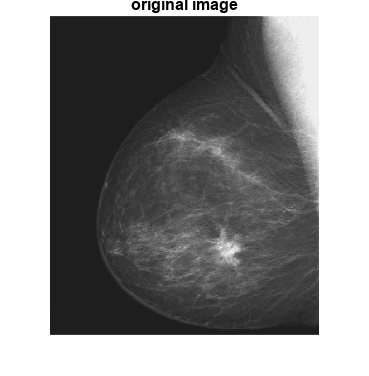

m=imread("Fig3.04(a).jpg");
imshow(m)
title("original image")

m1=double(m)

m1 =     22    30    32    28    27    28    28    29    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28
    38    26    39    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33
    35    21    43    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28
    38    33    32    33    33    33    33    33    33    33    33    33    33    33    33  

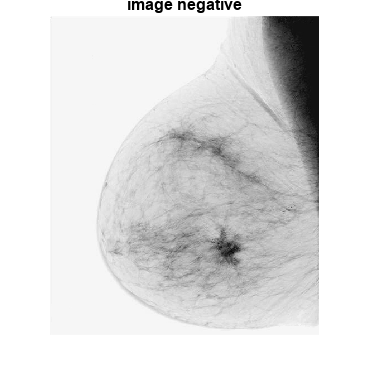

out=255-m1;
imshow(out,[])
title("image negative")

ex2  Log transformations

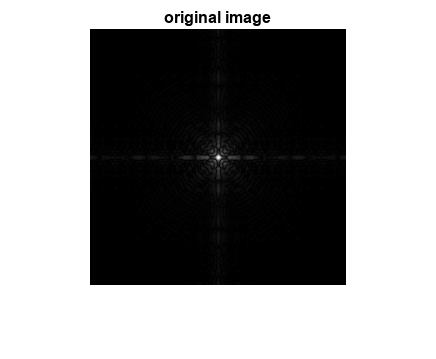

d=imread("Fig3.05(a).jpg");
imshow(d)
title("original image")

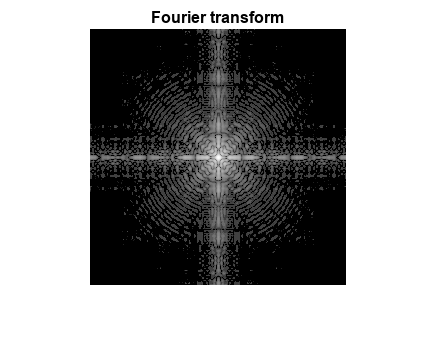

d1=double(d);
s=log(1+d1);
imshow(s,[])
title("Fourier transform")

ex3 Power-law transformations

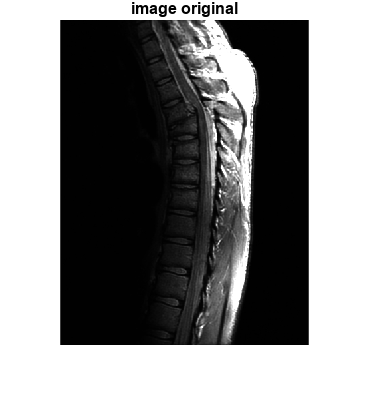

b=imread("Fig3.08(a).jpg");
imshow(b)
title("image original")

b=double(b)

b =      0     1     1     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     1     1     0     0     1     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     0     0     1
     0     1     1     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     0     1     1     1     1     1     1     0     0     1     1     0     1     1     1     1     1     1     2     1     1     1     1
     1     1     0     0     1     1     1     0     0     1     1     2     2     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     2     1     0     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1   

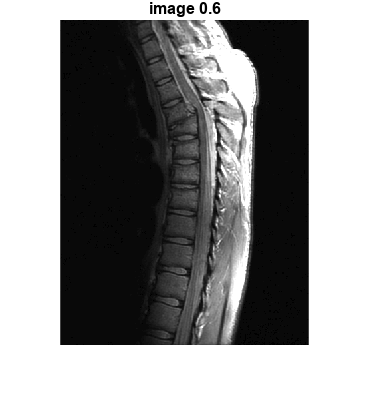

b1=b.^0.6;
imshow(b1,[])
title("image 0.6")

ex4 Lookup tables (LUT)

T=uint8(floor((0:255)/2));
ct=T(255);
ct=double(ct)

ct = 127

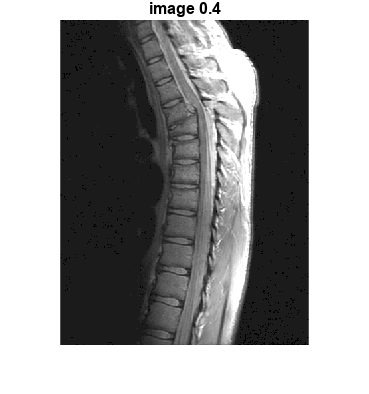

b2=ct.*(b.^0.4);
imshow(b2,[])
title("image 0.4")

ex4

f=imread("Fig3.13.jpg")

f = 600×608 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

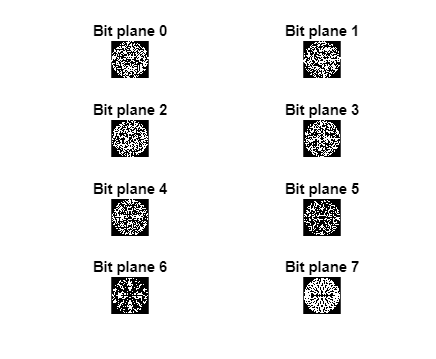

subplot(4,2,1)
c0=mod(f, 2);
imshow(c0,[]);
title("Bit plane 0")
subplot(4,2,2)
c1=mod(floor(f/2), 2);
imshow(c1,[]);
title("Bit plane 1")
subplot(4,2,3)
c2=mod(floor(f/4), 2);
imshow(c2,[]);
title("Bit plane 2")
subplot(4,2,4)
c3=mod(floor(f/8), 2);
imshow(c3,[]);
title("Bit plane 3")
subplot(4,2,5)
c4=mod(floor(f/16), 2);
imshow(c4,[]);
title("Bit plane 4")
subplot(4,2,6)
c5=mod(floor(f/32), 2);
imshow(c5,[]);
title("Bit plane 5")
subplot(4,2,7)
c6=mod(floor(f/64), 2);
imshow(c6,[]);
title("Bit plane 6")
subplot(4,2,8)
c7=mod(floor(f/128), 2);
imshow(c7,[]);
title("Bit plane 7")